#### Check how autorcorrelation graph is affected by removing outlier data (ten minutes of blackout).

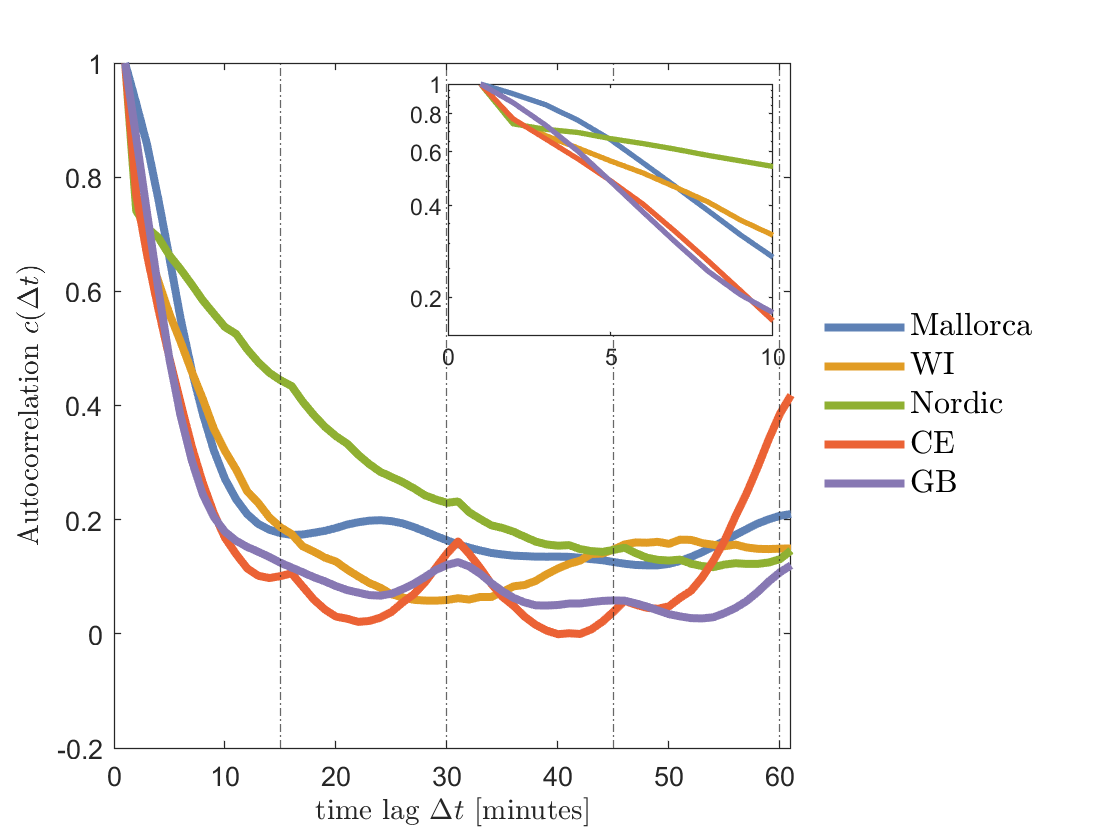

tic;
legendList = {};
maxLag = 60;
grids = {'spain_mallorca','us_wi','nordic', ...
    'continental_europe', 'uk'};

addpath functions\

colors = [ [94,129,181] 
    [225,156,36]
    [143,176,50]
   [235,98,53]
  [135,120,179]]/255;

alreadyPlotted = zeros(1,5);
tau_min = zeros(1,5);
legendList = {'Mallorca','WI','Nordic','CE','GB'};

i = 1;
for grid = grids
    [years,months] = selectTimePeriod(grid);
    for year = years
        for month = months
            if dataExists(grid,year,month) && ~alreadyPlotted(i)
                filename = selectInput(grid,year,month,0);
                fautocorr = readmatrix(strcat(filename,'_fautocorr.txt'));
                logOfInitialAutocorrs = log10(fautocorr(1:10));
                timeLags = [1:10]-1;
                coefficients = polyfit(timeLags, logOfInitialAutocorrs, 1);
                slope = coefficients(1);
                tau_min(i) = -slope;
                p = plot(fautocorr);
                p.Color = colors(i,:);
                p.LineStyle = '-';
                p.LineWidth = 3.0;
                hold on;
                alreadyPlotted(i) = 1;
            else
                continue;
            end
        end
    end
    i = i + 1;
end

hold off;
ylabel('Autocorrelation $c(\Delta t)$',"Interpreter","latex")
xlabel('time lag $\Delta t$ [minutes]','Interpreter',"latex")
xlim([0 maxLag+1]);

for x = 15:15:maxLag
    xline(x,'-.');
end
alreadyPlotted = zeros(1,5);
legend(legendList, ...
    'Interpreter',"latex", ...
    'Location',"eastoutside", ...
    'Box',"off",'FontSize',12);


axes('Position',[.40 .6 .29 .3],'Box',"on")

figure(1);
i = 1;
for grid = grids
    [years,months] = selectTimePeriod(grid);
    for year = years
        for month = months
            if dataExists(grid,year,month) && ~alreadyPlotted(i)
                filename = selectInput(grid,year,month,0);
                fautocorr = readmatrix(strcat(filename,'_fautocorr.txt'));
                p2 = plot(fautocorr(1:10));
                p2.Color = colors(i,:);
                p2.LineStyle = '-';
                p2.LineWidth = 2.0;
                hold on;
                alreadyPlotted(i) = 1;
            else
                continue;
            end
        end
    end
    i = i + 1;
end
ylim([0.15 1.0]);
set(gca, 'YScale', 'log');

tau_min

tau_min =     0.0654    0.0498    0.0235    0.0829    0.0879


toc;

Elapsed time is 6.496274 seconds.


% addpath github_repo\src\
% matlab2tikz('figurehandle',figure(1),'filename','test1.tex' ,'standalone', true,'showInfo',false);

% toc;

Elapsed time is 14.233379 seconds.
